close; clear; clc;

## config

Freq_Offset = 0.1; % normalised frequency
SNR = 30; % dB

## Transmitter

config

Amount_of_Frame = 40;
Length_Data_IQ = 1440;

% Start of frame
SOF = [1 0 0 1 1 1 0 1 0 1 0 1 0 1 1 0 0 1 0 0];
IQ_SOF = mapping(SOF, "BPSK"); % Use this sequence on the Rx as a Pilot-Signal

% bit generator

% QAM | mapper
% Generate vector of bits with length = Amount_of_Frame*Length_Data_IQ
rng default;

Bit_depth_Dict = 2;
Tx_Bits = randi([0,1], 1, Bit_depth_Dict * Length_Data_IQ*Amount_of_Frame);
% Use your function Mapping.m from previous courses
TX_IQ_Data = mapping(Tx_Bits, "QPSK");

% Frame structure 
% |20 IQ BPSK Start-of-Frame| 1440 IQ QPSK| ... 
IQ_TX_Frame = FrameStruct(TX_IQ_Data, IQ_SOF, Amount_of_Frame);

## Channel

Add white Gaussian noise to signal

Channel_IQ = awgn(IQ_TX_Frame, SNR, 'measured');

% Add frequency offset
Channel_IQ_framed = Channel_IQ.*exp(-1j.*2.*(1:length(Channel_IQ)).*pi*Freq_Offset);

Channel_IQ_channel = reshape(Channel_IQ_framed.',1,[]);

## TEST

cor = Correlation(IQ_SOF, Channel_IQ_channel, 0);

plot(cor);

## Receiver with frequency estimator based on Delay and Multiply with D=2

in feedback scheme

% Configurate the Loop Filter
% =========================================================================
% Loop filter preset
% -------------------------------------------------------------------------
Xi = 1;           % detector gainDampingFactor
BnTs = 0.001;       % Normalized loop bandwidth (Ts = 1 for this problem)
Kd = 2*pi;          % Phase (not change)
K0 = 1;             % not change
% =========================================================================
%> Loop filter coefficient calculation
% -------------------------------------------------------------------------
% todo прописать расчет коэффициентов фильтра
% > Proportional coefficient
Kp = 1/Kd/K0*4*Xi/(Xi+1/4/Xi)*BnTs;
% > Integrator coefficient
Ki = 1/Kd/K0*4/(Xi+1/4/Xi)^2*BnTs^2;

% TASK
% pay attention to frame structure
frame_len = Length_Data_IQ + length(IQ_SOF);
[RX_IQ_DM, DM_estimate] = DM(Channel_IQ_channel, frame_len, Kp, Ki, IQ_SOF,2);


## **Accuracy of the DM algorithm from the frequency shift in the channel. Accuracy is assessed using the RMSE metric**

expir_count = 100;
rms = [];
for Freq_Offset= -0.5:0.01:0.5
    tmp_s = 0;
    for j = 1:expir_count
        Channel_IQ = awgn(IQ_TX_Frame, SNR, 'measured');
        Channel_IQ_framed = Channel_IQ.*exp(-1j.*2.*(1:size(Channel_IQ,2)).*pi*Freq_Offset);
        Channel_IQ_channel = reshape(Channel_IQ_framed.',1,[]);
        [RX_IQ_DM, DM_estimate] = DM(Channel_IQ_channel, frame_len, Kp, Ki, IQ_SOF, 2);
        tmp = RMSE(DM_estimate, Freq_Offset);
        tmp_s = tmp_s + tmp;
    end
    rms  = [rms, tmp_s/expir_count];
end

## **Grafic which demonstrate acuuracy of the DM algorithm with D = 2**

Freq_Offsets = -0.5:0.01:0.5;
semilogy(Freq_Offsets, rms);
title('Delay & Multiply Estimator, D = 2');
xlabel('Norm. freq offset',"FontSize", 10);
ylabel('Norm. RMSE freq. offset',"FontSize", 10);

## **RMSE from freq_offset for different values of D = 2, 4, 8**

expir_count = 100;
all_rms = [];
D = [2,4,8]
for i = 1 : 3
    rms = [];
    for Freq_Offset= -0.5:0.01:0.5
        tmp_s = 0;
        for j = 1 : expir_count
            Channel_IQ = awgn(IQ_TX_Frame, SNR, 'measured');
            Channel_IQ_framed = Channel_IQ.*exp(-1j.*2.*(1:size(Channel_IQ,2)).*pi*Freq_Offset);
            Channel_IQ_channel = reshape(Channel_IQ_framed.',1,[]);
            [RX_IQ_DM, DM_estimate] = DM(Channel_IQ_channel, frame_len, Kp, Ki, IQ_SOF, D(i));
            tmp = RMSE(DM_estimate, Freq_Offset);
            tmp_s = tmp_s + tmp;
        end
        rms  = [rms, tmp_s / expir_count];
    end
    all_rms = [all_rms; rms];
end

## **Grafic which demonstrate acuuracy of the DM algorithm with D = 2, 4, 8**

Freq_Offsets = -0.5:0.01:0.5;
D = [2,4,8];
for i=1 : length(D)
   semilogy(Freq_Offsets, all_rms(i, :),"DisplayName","D = " + string(D(i)))
   hold on;
end
legend('FontSize', 10);
xlabel('Norm. frequency offset',"FontSize", 10);
ylabel('Norm. RMSE freq. offset',"FontSize", 10);
hold off;

## Receiver with frequency estimator based on Luise and Reggiannini for N = 2

in feedforward scheme

% TASK
% pay attation to frame structure

[RX_IQ_LR, LR_estimate] = LR(Channel_IQ_channel, IQ_SOF, 2);


plot((1:Amount_of_Frame), LR_estimate,"LineWidth", 2)
xlabel('Pilot block number',"FontSize", 10)
ylabel('Norm. freq offset (NCO)',"FontSize", 10)

expir_count = 100;
rms = [];
for Freq_Offset=[-0.5:0.01:0.5]
    tmp_s = 0;
    for j = 1:expir_count
        Channel_IQ = awgn(IQ_TX_Frame, SNR, 'measured');
        Channel_IQ_framed = Channel_IQ.*exp(-1j.*2.*(1:size(Channel_IQ,2)).*pi*Freq_Offset);
        Channel_IQ_channel = reshape(Channel_IQ_framed.',1,[]);
        [RX_IQ_LR, LR_estimate] = LR(Channel_IQ_channel, IQ_SOF,2);
        tmp = RMSE(LR_estimate, Freq_Offset);
        tmp_s = tmp_s + tmp;
    end
    rms  = [rms, tmp_s / expir_count];
end

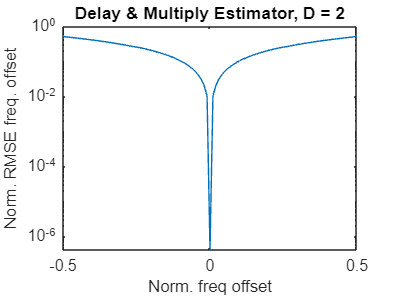

Freq_Offsets = [-0.5:0.01:0.5];
semilogy(Freq_Offsets, rms)
xlabel('Norm. freq offset',"FontSize", 10)
ylabel('Norm. RMSE freq. offset',"FontSize", 10)

## **RMSE from freq_offset for different values of N**

expir_count = 100;
rms_all = [];
for N = [2,4,8]
    rms = [];
    for Freq_Offset = -0.5:0.01:0.5
        tmp_s = 0;
        for j = 1 : expir_count
            Channel_IQ = awgn(IQ_TX_Frame, SNR, 'measured');
            Channel_IQ_framed = Channel_IQ.*exp(-1j.*2.*(1:size(Channel_IQ,2)).*pi*Freq_Offset);
            Channel_IQ_channel = reshape(Channel_IQ_framed.',1,[]);
            [RX_IQ_LR, LR_estimate] = LR(Channel_IQ_channel, IQ_SOF,N);
            tmp = RMSE(LR_estimate, Freq_Offset);
            tmp_s = tmp_s + tmp;
        end
        rms  = [rms, tmp_s / expir_count];
    end
    rms_all = [rms_all; rms];
end

Freq_Offset = -0.5:0.01:0.5;
N = [2,4,8];
for i=1:3
   semilogy(Freq_Offset,rms_a(i,:),1,"DisplayName","N = "+string(N(i)))
   hold on;
end
legend('FontSize', 10);
xlabel('Norm. frequency offset',"FontSize", 10);
ylabel('Norm. RMSE freq. offset',"FontSize", 10);
hold off;

## NDA (Costas loop)

Freq_Offset = 0.01;

SNR = 30;
Tx_Bits = randi([0 1], 1,10000);
TX_IQ_Data = mapping(Tx_Bits, "QPSK");
Channel_IQ = awgn(TX_IQ_Data, SNR, 'measured');
Kp=3e-5;
Ki=9e-8;

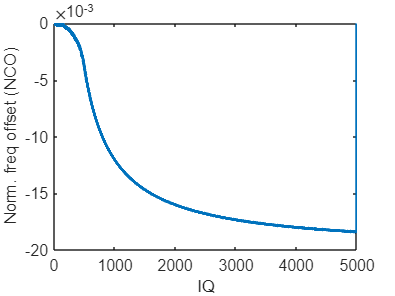

Channel_IQ = Channel_IQ.*exp(-1j.*2.*(1:length(Channel_IQ)).*pi.*Freq_Offset);
[RX_IQ_Costas, Costas_estimate] = Costas(Channel_IQ, Ki, Kp);
plot((1:length(Channel_IQ)),Costas_estimate,"LineWidth", 2)
xlabel('IQ',"FontSize", 10)
ylabel('Norm. freq offset (NCO)',"FontSize", 10)

## **RMSE from freq_offset in channel**

expir_count = 1000;
rms = [];
for Freq_Offset = -0.5:0.01:0.5
    tmp_s = 0;
    for j = 1:expir_count
        Channel_IQ = awgn(TX_IQ_Data, SNR, 'measured');
        Channel_IQ = Channel_IQ.*exp(-1j.*2.*(1:length(Channel_IQ)).*pi.*Freq_Offset);
        [RX_IQ_LR, LR_estimate] = Costas(Channel_IQ, Ki,Kp);
        tmp = RMSE(LR_estimate, Freq_Offset);
        tmp_s = tmp_s + tmp;
    end
    rms  = [rms, tmp_s / expir_count];
end

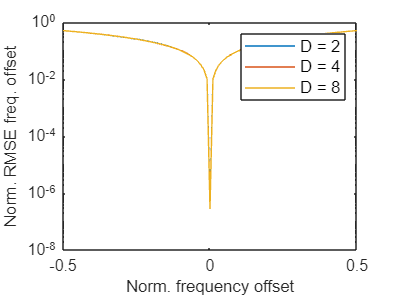

Freq_Offset = -0.5:0.01:0.5;
semilogy(Freq_Offset,rms,'LineWidth', 1)
xlabel('Norm. freq offset',"FontSize", 10)
ylabel('Norm. RMSE freq. offset',"FontSize", 10)

## Analysis

========================================================================= TASK Compare results and make a conclusion Compare the RMSE for different frequency offsets for both synchronisation schemes Compare the time of synchronisation -------------------------------------------------------------------------